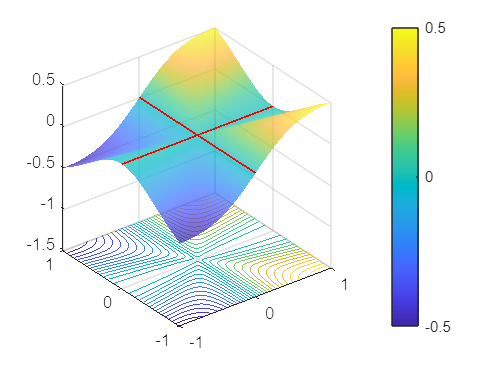

xs = linspace(-1, 1);
ys = linspace(-1, 1);
t = linspace(-1, 1);
[X,Y] = meshgrid(xs, ys);
f =  @(x, y) (x.*y.^2)./(x.^2 + y.^2);
Z = f(X,Y);
Z(Z ~= real(Z)) = NaN;
zcs = linspace(min(Z(:)), max(Z(:)), 30);
figure(1)
surf(X,Y,Z,EdgeColor="none", EdgeAlpha=.7 ,FaceAlpha=.7)
hold on;
[M,c] = contour(X,Y, Z,zcs);
c.ZLocation=-1.5;
colorbar;
zers = zeros(size(t));
plot3(t, zers, f(t, zers), Color='red', LineWidth=1)
plot3(zers, t, f(zers, t), Color='red', LineWidth=1)
daspect([1 1 1]);
hold off;

figure(4)
f9 = @(x, y, z) x.^2 + y.^2 + z.^2 - 9;
f4 = @(x, y, z) x.^2 + y.^2 + z.^2 - 4;
f1 = @(x, y, z) x.^2 + y.^2 + z.^2 - 1;
fimplicit3(f9, [0 3 -3 3 -3 3], EdgeColor='interp', FaceColor='red')
hold on
fimplicit3(f4, [0 3 -3 3 -3 3], EdgeColor='interp', FaceColor='blue')
fimplicit3(f1, [0 3 -3 3 -3 3], EdgeColor='interp', FaceColor='green')
xlim([-3 3]);
daspect([1 1 1])
hold off;

g = @(x, y, z) log(z.*(x + y));
fimplicit3(g)
daspect([1 1 1])